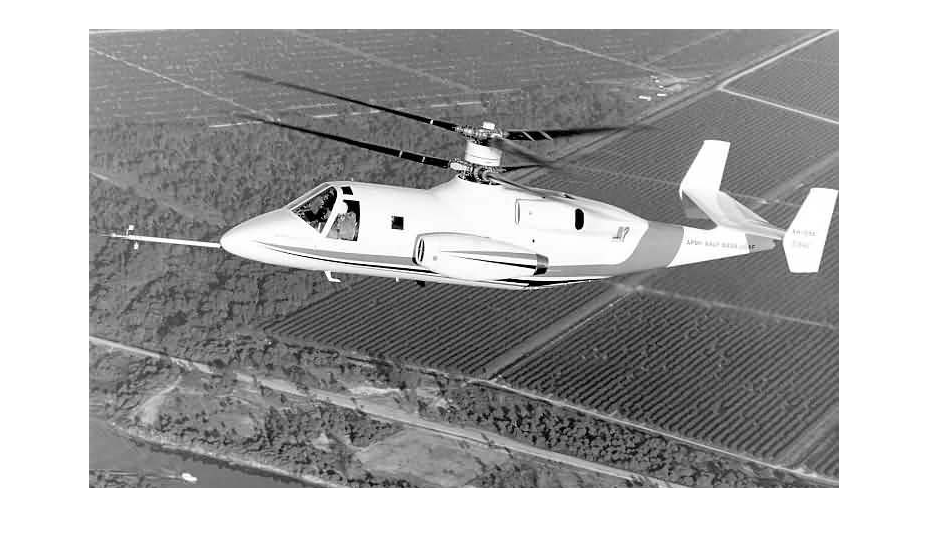

clear all
imshow(imread("XH59A.jpg"))

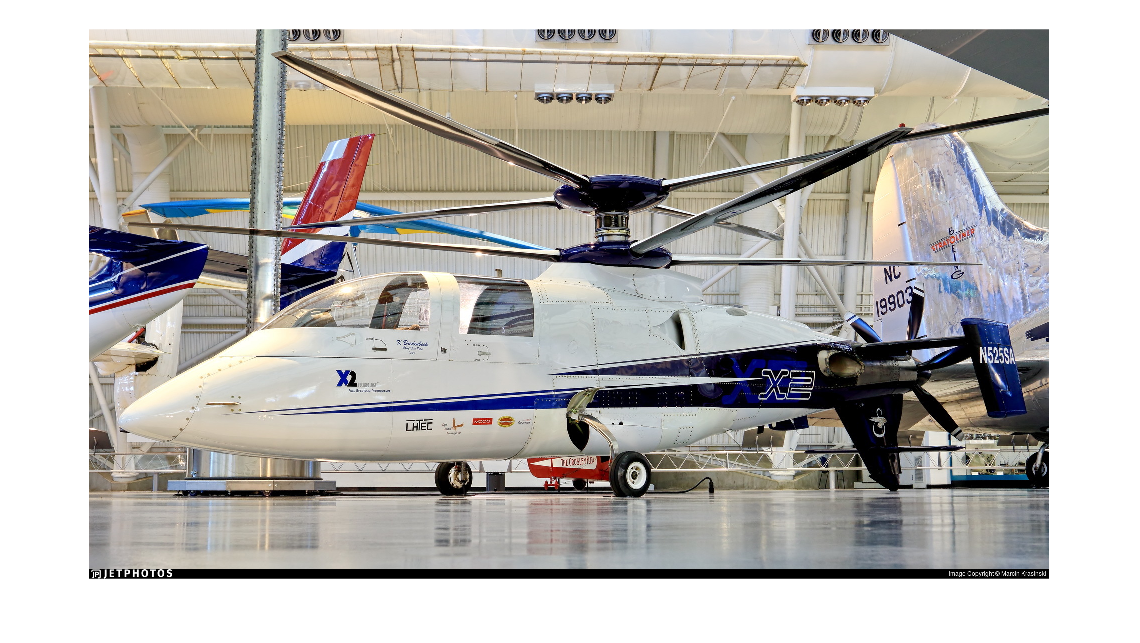

imshow(imread("Sikorsky_X2.jpg"))

# 设置基本参数（全局变量）

% 飞行高度(海平面）
h = 0;
% 大气数据
[~,~,~,rho] = atmosisa(h); %温度，音速，压强，密度
% 上下旋翼各自桨叶数
N_b = 3;
% 上下旋翼间距 m
z_diff = 0.77;
% 主旋翼半径 m
R = 5.49;
%桨盘面积
A = pi*R^2;
% 主旋翼转速rad/s
Omega = 35.9;
% 主旋翼实度
sigma_M = 0.127;
% 主旋翼桨叶扭转角 rad
theta_t = deg2rad(-10);
% 主旋翼一阶挥舞固有频率 
omega_n = 1.4*Omega;
% 主旋翼挥舞惯性矩 kg/m^2
I_beta = 450;
% 推进桨半径 m
R_PR = 1.3;
% 推进桨转速 rad/s
Omega_PR = 162;
% 推进桨实度
sigma_PR = 0.2;
% 推进桨叶扭转
theta_t_PR = deg2rad(-30);
% 主旋翼，推进桨叶升力线斜率,NACA0012
a = 5.7;
a_PR = 5.7;
%主旋翼，推进桨叶阻力系数
c_d = 0.008;
c_dPR = 0.008;
% 主旋翼桨叶弦长m
c = 0.29;
% K_beta 弹簧刚度  Nm/rad
K_beta = 220500

K_beta = 220500

% 主旋翼洛克数 
gamma_M = 5.41;
% 整机质量 kg
GW = 5500;
% 无量纲等效铰偏置量 0.4左右
epsilon = 2*((omega_n/Omega)^2-1)/(1+2*(omega_n/Omega)^2);
% 主旋翼对挥舞铰的质量静矩 200多
% M_beta = 1/2*R^2*m_b/R;
M_beta = I_beta*3/2*(1/R)/(1-epsilon);
% 主旋翼桨毂纵向安装角
i_theta = deg2rad(3);
% 主旋翼桨毂横向安装角
i_phi = 0;
% 重力加速度
g = 9.81;
%转动惯量
Ixx = 5518;
Iyy = 26844;
Izz = 23048;
%推进桨叶坐标
x_PR = -7.66;
y_PR = 0;
z_PR = 0;
% 机身气动中心
x_F = 0;
y_F = 0;
z_F = 0;
% 主旋翼位置 1：下旋翼，2：上旋翼
x_H1 = 0;
y_H1 = 0;
z_H1 = -0.89;
x_H2 = 0;
y_H2 = 0;
z_H2 = z_H1-z_diff;

l_F = 12;

拟合气动参数

run dataFit.m

测试：根据mu计算上下旋翼气动干扰delta_l,u的值

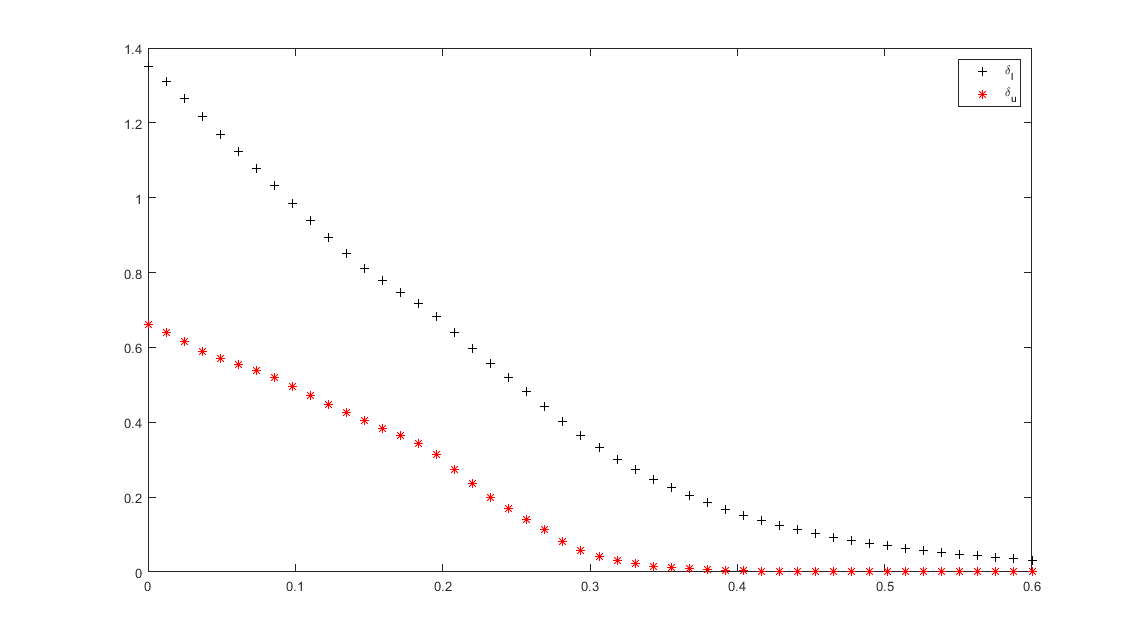

%delta_l：上对下干扰<2,比较大 delta_u：下对上干扰<1
%delta_l = 1.2;
%delta_u = 0.8;  

runtest = false;
if runtest == true
    clf
    for mu = linspace(0,0.6,50)
        run calculateDelta_lu.m
        plot(mu,delta_l,'k+',mu,delta_u,'r*')
        hold on
        legend('\delta_l','\delta_u')
    end
end

global A_1
global L_H1B1 L_H2B2
global L_S1H1 L_S2H2
global alpha_F beta_F

global q_F
global s_F 
s_F = pi*2.4^2*10;

global K_PR
K_PR = 1;
global v_0PR


global kappa
kappa = 0.5;
global x_HS y_HS z_HS
x_HS = -6.8;
y_HS = 0;
z_HS = 0.2;
global alpha_0HS %平尾安装角
alpha_0HS = 0;
global k_e; %平尾升降舵效率因子
k_e = 0.8;
global s_e s_h
s_h = 5.57;
s_e = s_H*0.4; %舵面占40%
global xi_H %平尾后掠角
xi_H = 0;
global C_XHalpha
C_XHalpha = 2.29;

## 初始化

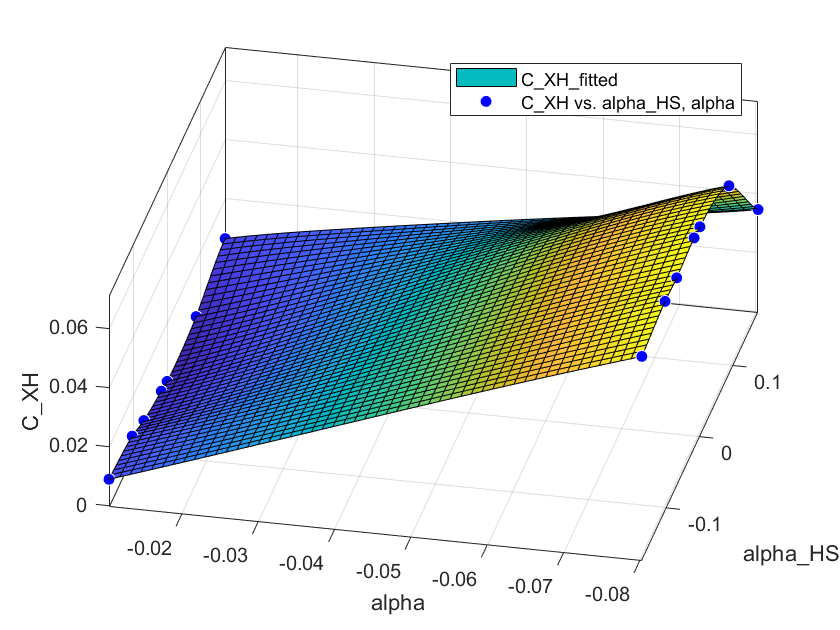

     Thin-plate spline interpolant:
       C_XH_fitted(x,y) = thin-plate spline computed from p
       where x is normalized by mean -0.01496 and std 0.1131
       and where y is normalized by mean -0.04538 and std 0.03622
     Coefficients:
       p = coefficient structure



gof = 包含以下字段的 struct :
           sse: 1.3670e-32
       rsquare: 1
           dfe: 0
    adjrsquare: NaN
          rmse: NaN


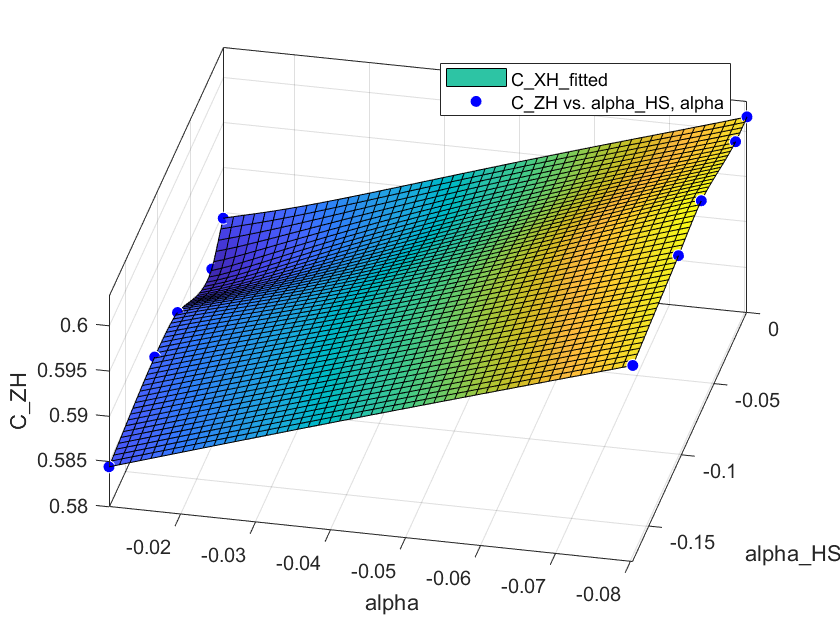

     Thin-plate spline interpolant:
       C_ZH_fitted(x,y) = thin-plate spline computed from p
       where x is normalized by mean -0.0733 and std 0.06623
       and where y is normalized by mean -0.04538 and std 0.03679
     Coefficients:
       p = coefficient structure



gof = 包含以下字段的 struct :
           sse: 2.4652e-31
       rsquare: 1
           dfe: 0
    adjrsquare: NaN
          rmse: NaN


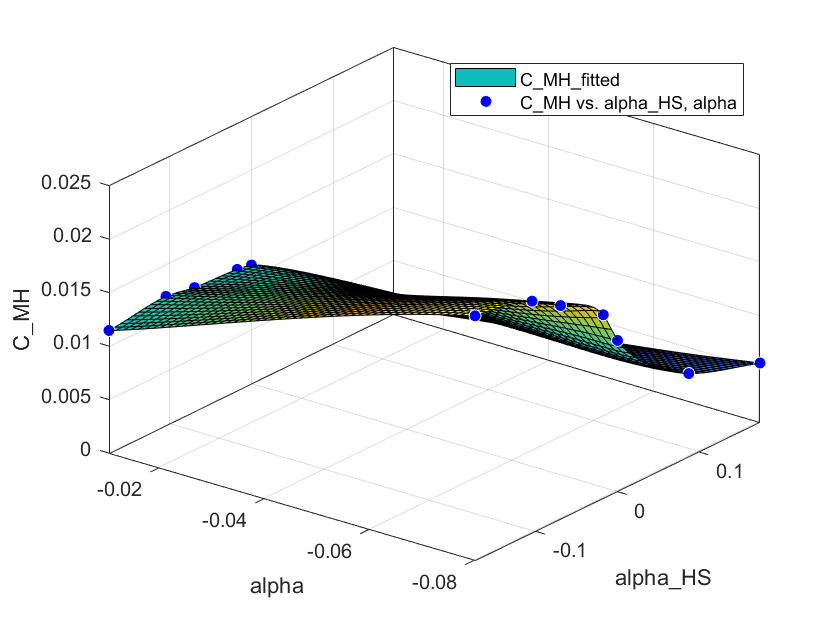

     Thin-plate spline interpolant:
       C_MH_fitted(x,y) = thin-plate spline computed from p
       where x is normalized by mean -0.01496 and std 0.1131
       and where y is normalized by mean -0.04538 and std 0.03622
     Coefficients:
       p = coefficient structure



gof = 包含以下字段的 struct :
           sse: 3.4325e-33
       rsquare: 1
           dfe: 0
    adjrsquare: NaN
          rmse: NaN


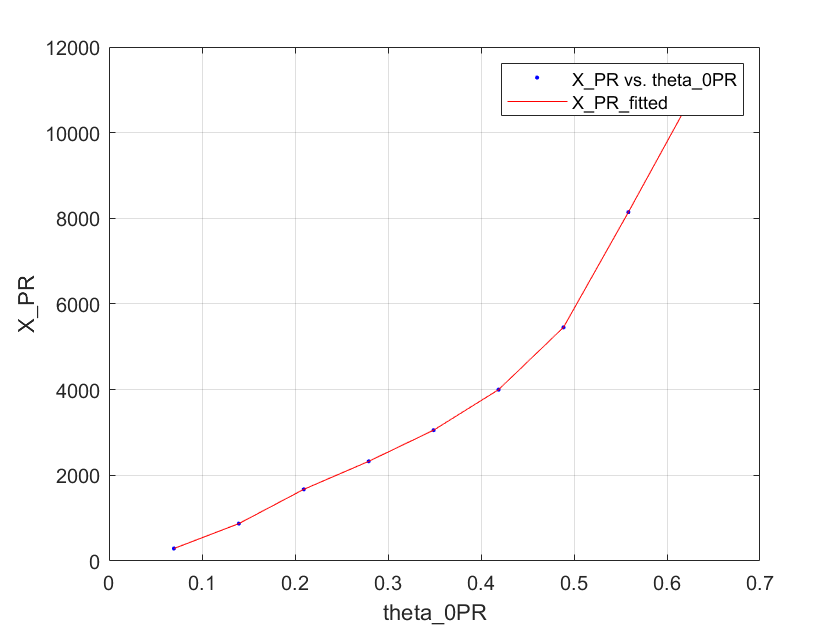

X_PR_fitted =      Linear interpolant:
       X_PR_fitted(x) = piecewise polynomial computed from p
       where x is normalized by mean 0.3491 and std 0.1912
     Coefficients:
       p = coefficient structure

gof = 包含以下字段的 struct :
           sse: 0
       rsquare: 1
           dfe: 0
    adjrsquare: NaN
          rmse: NaN


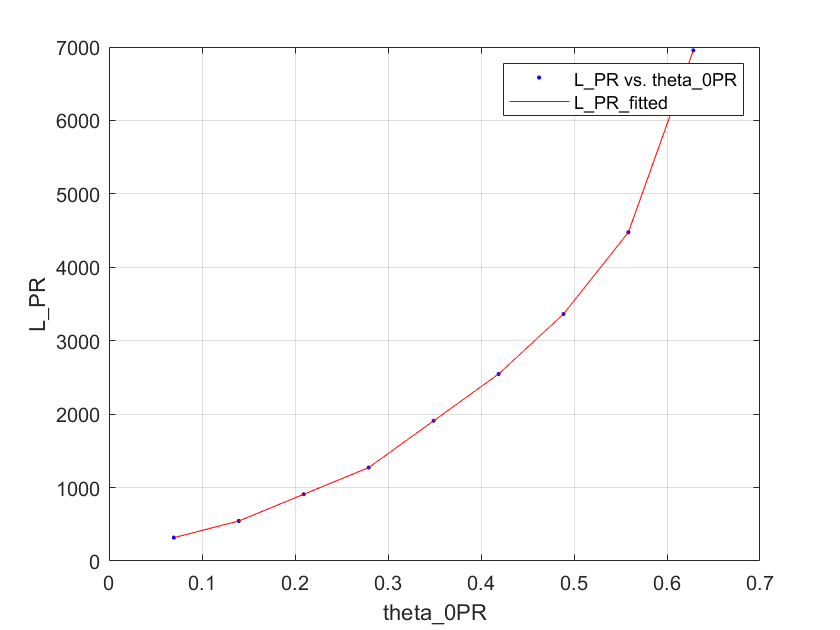

L_PR_fitted =      Linear interpolant:
       L_PR_fitted(x) = piecewise polynomial computed from p
     Coefficients:
       p = coefficient structure

gof = 包含以下字段的 struct :
           sse: 0
       rsquare: 1
           dfe: 0
    adjrsquare: NaN
          rmse: NaN


run CurveFitting.mlx

u = 0.0001;
v = 0.000000001;
w = 0.00000001;
w_dot = 0;
p = 0;
q = 0;
r = 0;
a_dot_01 = 0;
a_ddot_01 = 0;
b_dot_11 = 0;
a_dot_11 = 0;
a_dot_02 = 0;
a_ddot_02 = 0;
b_dot_12 = 0;
a_dot_12 = 0;

A_1 = 0;
B_1 = 0;
v_1 = 10;
v_2 = 20;
v_0PR = 14.5/(Omega_PR*R_PR);
a_01 = 0.1;
a_11 = 0.01;
b_11 = 0.01;

a_02 = 0.1;
a_12 = 0.01;
b_12 = 0.01;

theta_0 = 10/180*pi; %rad
theta_diff = 0;

T_HB = [cos(i_theta)              0           -sin(i_theta);
        sin(i_theta)*sin(i_phi)   cos(i_phi)  cos(i_theta)*sin(i_phi);
        sin(i_theta)*cos(i_phi)   -sin(i_phi) cos(i_theta)*cos(i_phi)];
L_H1B1 = T_HB;
L_H2B2 = T_HB;

phi = 0;
theta = 0;
psi = 0;

theta_0PR = 10/180*pi; %rad

delta_elev = 0; %下偏为正


[mu_1,mu_2] = Calculate_mu();
[lambda_1,lambda_2] = Calculate_lambda();
lambda_1 = -lambda_1;
lambda_2 = -lambda_2;
[u_H1H1, v_H1H1, w_H1H1] = Calculate_uvw_H1H1();
[u_H2H2, v_H2H2, w_H2H2] = Calculate_uvw_H2H2();
beta_S1 = asin(v_H1H1/sqrt(u_H1H1^2+v_H1H1^2));
beta_S2 = asin(v_H2H2/sqrt(u_H2H2^2+v_H2H2^2));
L_S1H1 = [cos(beta_S1)     sin(beta_S1) 0;
         -sin(beta_S1)    cos(beta_S1)  0;
            0               0           1];
L_S2H2 = [cos(beta_S2)     sin(beta_S2) 0;
         -sin(beta_S2)    cos(beta_S2)  0;
            0               0           1];
[p_S1,q_S1] = Calculate_pq_S1();
[p_S2,q_S2] = Calculate_pq_S2();
Chi_1 = atan(-mu_1/lambda_1);
Chi_2 = atan(-mu_2/lambda_2);
K_1 = 15*pi/32*tan(Chi_1/2);
K_2 = 15*pi/32*tan(Chi_2/2);

run RotorForceMoment.m %BUAA

LowerRotorForce = 	1.0e+05 *

   -0.0199
    0.0248
   -2.0743


LowerRotorMoment = 	1.0e+05 *

    0.0521
   -0.0051
    1.0689


UpperRotorForce = 	1.0e+05 *

   -0.0168
   -0.0216
   -1.8034


UpperRotorMoment = 	1.0e+05 *

   -0.0659
    0.0050
   -1.5699


%下旋翼平均诱导速度
T_W1 = 2*rho*A*v_1*sqrt(u_H1H1^2+v_H1H1^2+(-w_H1H1+v_1+delta_l*v_2)^2)

T_W1 = 8.3060e+04

%上旋翼平均诱导速度
T_W2 = 2*rho*A*v_2*sqrt(u_H2H2^2+v_H2H2^2+(-w_H2H2+v_2+delta_u*v_1)^2)

T_W2 = 1.3681e+05

run FuselageForceMoment.m %NUAA

FuselageForce = 	1.0e+-4 *

    0.2154
    0.0140
    0.0000


FuselageMoment =    -0.0000
    0.0015
   -0.0000


%run PropellerForceMomentBUAA.m %BUAA
%C_TPR = v_0PR*4*sqrt((v_0PR-lambda_PR)^2 + v_bar_PR^2 + w_bar_PR^2)
run PropellerForceMomentNUAA.m

PropellerForce =         1273
           0
           0


PropellerMoment =   727.2700
         0
         0


run HorizontalTailForceMoment.m

L_elev = 0

C_XH = -0.1172

C_ZH = 0.6175

C_MH = -0.0503

HorizontalTailForce = 	1.0e+03 *

    1.5972
    0.0000
    0.3032


HorizontalTailMoment = 	1.0e+03 *

   -0.0000
    2.3814
   -0.0000


# 需要求解的状态变量

总距 $\theta_0$，横向周期变距$A_1$，纵向周期变距$B_1$，推进螺旋桨桨距$\theta_{PR}$ 

总距差动$\theta_{diff}$，升降舵偏转$\delta_e$，升降舵差动$\delta_{ediff}$，方向舵偏转$\delta_r$

u,v,w,p,q,r 俯仰角$\theta$ 滚转角$\phi$ 偏航角$\psi$